%% Gs=(5+N/2)/(s*(0.5*s+1));
%Sx=-2+j2*sqrt(3)

clc
clear
N=4;
s=tf('s');
Gs=(5+N/2)/(s*(0.5*s+1))

Gs =
 
       7
  -----------
  0.5 s^2 + s
 
Continuous-time transfer function.



ProcentajeCriterioTs=0.02;
CriterioRiso=[0.10 0.90];
ParametroSys(Gs,ProcentajeCriterioTs,CriterioRiso) %el sistema es inestable en LO no se analiza mas nada

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    


Resultados =     '
     Ts(2.00)=NaN
     Tr=NaN
     Mp=NaN
     Tp=Inf
     Tao=NaN
     ValorF=Inf
     '


ans = NaN

% figure(1)
% step(Gs)
% figure(2)
% subplot(221),rlocus(Gs)
% subplot(223),nyquist(Gs)
% subplot(122),margin(Gs)
%% Calcular polos deseados y posicion
clc
close all
Sigma=2; %polos deseados (reales)
Wd=2*sqrt(3) %polos deseasdos imaginarios
Wn=sqrt(Sigma^2+Wd^2);
Zeta=Sigma/Wn

Zeta = 0.5000

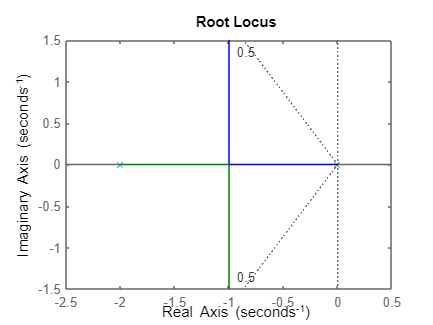

rlocus(Gs)
sgrid(Zeta,0)

[Phi,Theta,Alpha,P,Z,Kc,C]=CompensadorBisectriz_SigmaWdZeta(Gs,Sigma,Wd,Zeta,0)

Phi = 30

Theta = 30.0000

Alpha = 60.0000

P = 5.4641

Z = 2.9282

Kc = 1.3520

C =
 
  1.352 s + 3.959
  ---------------
     s + 5.464
 
Continuous-time transfer function.



rlocus(Gs)
%% 
clc
close all
GsC=C*Gs;

Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
Su=feedback(C,Gs); %señal de control
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.46e+00                 1.00e+00       3.46e+00         2.89e-01    
 -2.00e+00 + 3.46e+00i     5.00e-01       4.00e+00         5.00e-01    
 -2.00e+00 - 3.46e+00i     5.00e-01       4.00e+00         5.00e-01    


Resultados =     '
     Ts(2.00)=2.0418
     Tr=0.3705
     Mp=20.9637
     Tp=0.8520
     Tao=0.4439
     ValorF=1.0000
     '


ans = 2.0418

ErroEpEvEa(GsC)

ans = 0

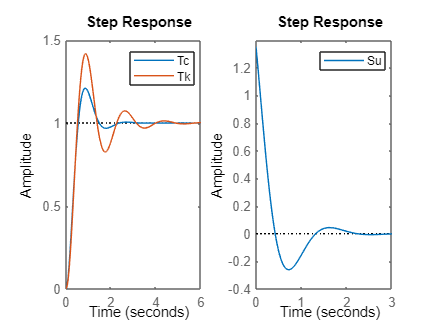

figure(2)
subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend

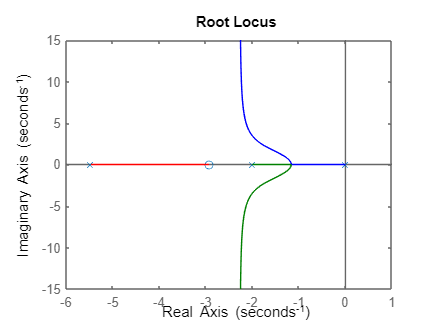

figure(3)
rlocus(GsC)